## Team:

#### 1- Samaa Khair - 20190481

#### 2- Mazen Allam - 202100669

# Block Diagrams

### Transmitter

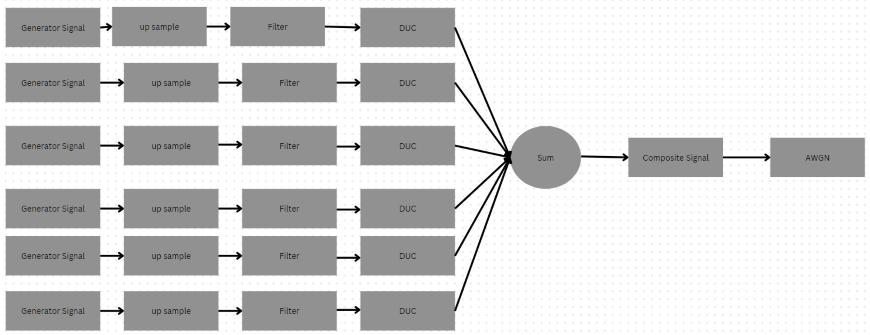

### Reciever

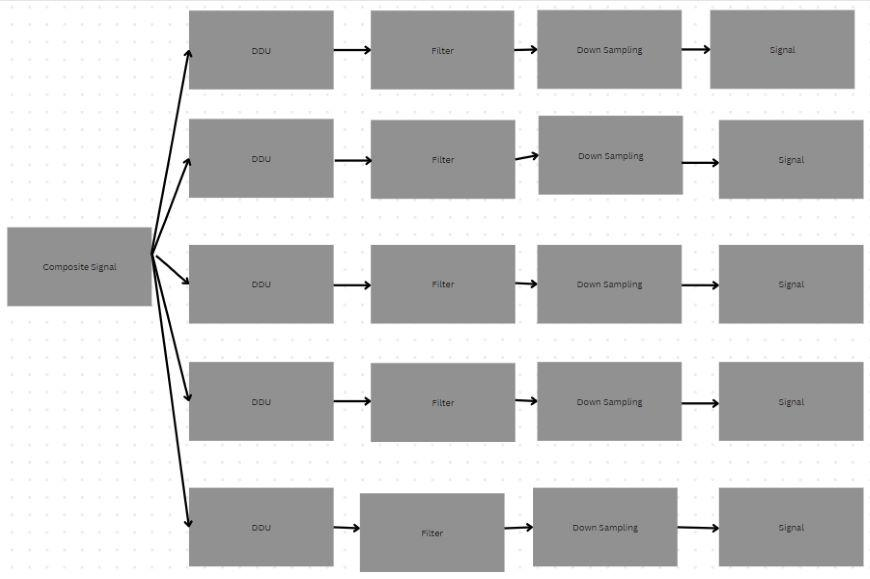

# Signals Generation

generates 6 NB-IoT signals, analyzes the frequency content of one signal using a spectral estimation technique, and visualizes the resulting power distribution across different frequencies.

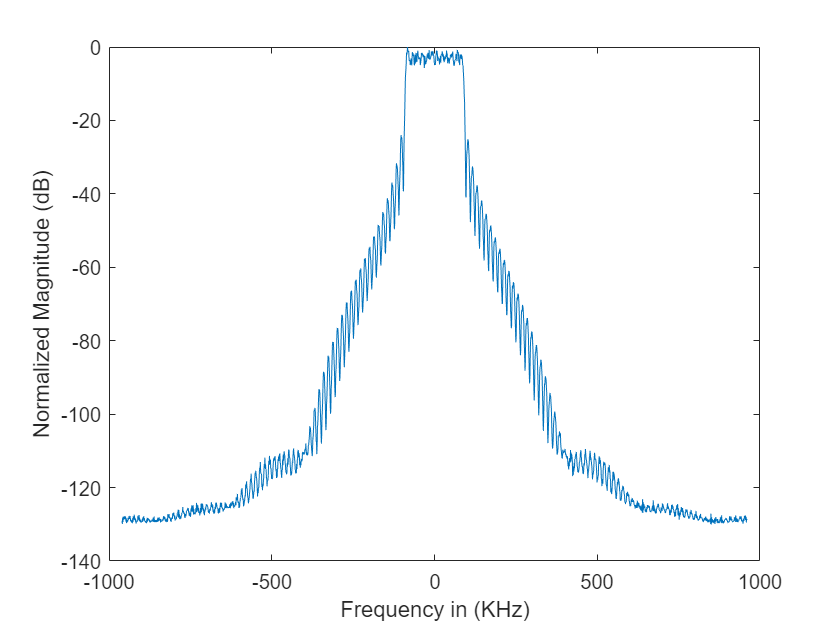

clc; clear; close all;

% Generating NB-IoT signals using provided function
waveforms = cell(1,6);
for i = 1:6
    [waveforms{i}, Fs] = generate_NBiot_UL();
end
[signal,~] = pwelch(waveforms(1),2048,1024,2048,Fs);
signal = signal/max(abs(signal));

% Shifting the zero-frequency component to the center for better visualization
centered_signal = fftshift(signal);

figure;
plot(linspace(-Fs/2, Fs/2, length(centered_signal))/1e3,20*log10(centered_signal))
xlabel('Frequency in (KHz)')
ylabel('Normalized Magnitude (dB)')

# Upsampling

performs upsampling on the previously generated NB-IoT signals to increase their sampling rate, analyzes the frequency content of one upsampled signal, and visualizes its power distribution across frequencies.

upsampling_factor = 3;

upsampled_waveforms = cell(1,6);
for i = 1:6
    upsampled_waveforms{i} = upsample(waveforms{i}, upsampling_factor)
end

upsampled_waveforms = 1×6 cell array
    {460800×1 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


upsampled_waveforms = 1×6 cell array
    {460800×1 double}    {460800×1 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


upsampled_waveforms = 1×6 cell array
    {460800×1 double}    {460800×1 double}    {460800×1 double}    {0×0 double}    {0×0 double}    {0×0 double}


upsampled_waveforms = 1×6 cell array
    {460800×1 double}    {460800×1 double}    {460800×1 double}    {460800×1 double}    {0×0 double}    {0×0 double}


upsampled_waveforms = 1×6 cell array
    {460800×1 double}    {460800×1 double}    {460800×1 double}    {460800×1 double}    {460800×1 double}    {0×0 double}


upsampled_waveforms = 1×6 cell array
    {460800×1 double}    {460800×1 double}    {460800×1 double}    {460800×1 double}    {460800×1 double}    {460800×1 double}


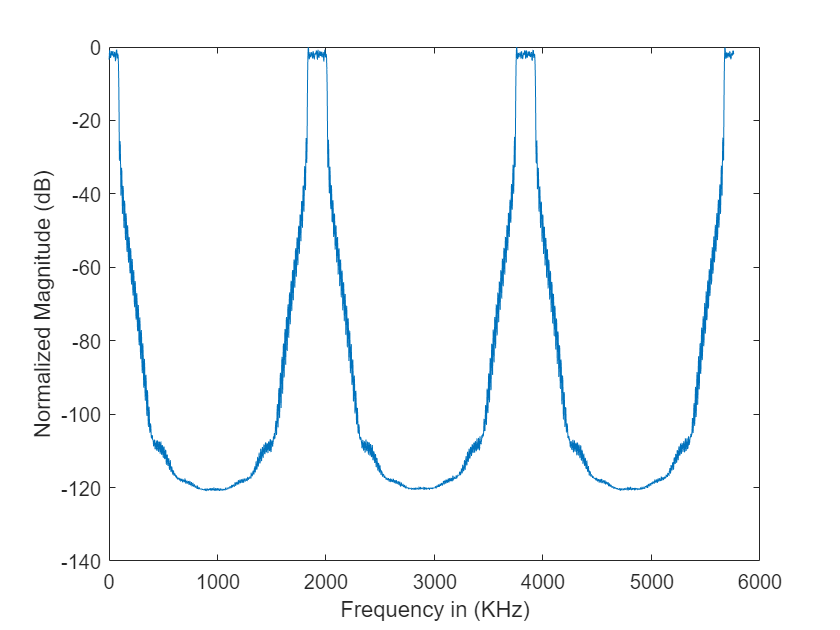

% The new sampling frequency after upsampling
Fs_new = Fs * upsampling_factor;

%calculating the Power Spectral Density of the first upsampled waveform 
[signal,f] = pwelch(upsampled_waveforms(1),2048,1024,2048,Fs_new);
signal = signal/max(abs(signal));

figure;
plot(f/1e3, 20*log10(signal));
xlabel('Frequency in (KHz)');
ylabel('Normalized Magnitude (dB)');

# FIR

applies a filter (identical to that used in reciever) to the previously upsampled NB-IoT signals, for shaping their frequency content and removing unwanted components. It then analyzes the spectral effect of the filtering and visualizes both the filtered signal's spectrum and the filter's frequency response.

Hd = filterOne();

Unrecognized function or variable 'filterOne'.

% Applying the FIR filter to the entire upsampled waveforms array
filtered_waveforms = cell(1,6);
for i = 1:6
    filtered_waveforms{i} = filter(Hd, upsampled_waveforms{i});
end
% Computing the Fourier Transform of the first filtered signal
fft_filtered_signal = fft(filtered_waveforms{1}, 2048);
% Generating frequency vector for plotting and shift it for centering at 0 Hz
fft_freq = linspace(-Fs_new/2, Fs_new/2, length(fft_filtered_signal));
% Shifting the zero-frequency component to the center of the spectrum
fft_filtered_signal_shifted = fftshift(fft_filtered_signal);
% Plotting the magnitude spectrum of the first filtered signal
figure;
plot(fft_freq/1e3, 20*log10(abs(fft_filtered_signal_shifted)/ ...
    max(abs(fft_filtered_signal_shifted))));
xlabel('Frequency (KHz)');
ylabel('Normalized Magnitude (dB)');
title('Magnitude Spectrum of the First Filtered Signal');
[h, w] = freqz(Hd);
figure;
plot(w/pi, 20*log10(abs(h)));  % Magnitude in dB
title('Filter Magnitude Response');
xlabel('Normalized Frequency (pi rad/sample)');
ylabel('Magnitude (dB)');

# Direct Up-Conversion (DUC):

Applies DUC to each filtered signal, shifting them to a carrier frequency of 180000 Hz, visualizes the spectrum of the first upconverted signal.

% Carrier Frequency for DUC
carrier_frequency = 180000
% Creating a time vector for the filtered signal
t_filtered = (0:length(upsampled_waveforms{1})-1)' / Fs_new;
% Applying DUC to the entire filtered waveforms array
upconverted_waveforms = cell(1,6);
for i = 1:6
    % Creation of the complex exponential carrier
    complex_carrier = exp(1j * 2 * pi * carrier_frequency * t_filtered);
    % Mixingg the signal with the complex carrier to shift it to the carrier frequency
    upconverted_waveforms{i} = filtered_waveforms{i} .* complex_carrier;
end
% Computing the Fourier Transform of the first upconverted signal for visualization
fft_upconverted_signal = fft(upconverted_waveforms{1}, 2048);
% Generating frequency vector for plotting and shift it for centering at 0 Hz
fft_freq_upconverted = linspace(-Fs_new/2, Fs_new/2, length(fft_upconverted_signal));
% Shifting the zero-frequency component to the center of the spectrum
fft_upconverted_signal_shifted = fftshift(fft_upconverted_signal);
% Plotting the magnitude spectrum of the first upconverted signal
figure;
plot(fft_freq_upconverted/1e3, 20*log10(abs(fft_upconverted_signal_shifted)/ ...
    max(abs(fft_upconverted_signal_shifted))));
xlabel('Frequency (KHz)');
ylabel('Normalized Magnitude (dB)');
title('Magnitude Spectrum of the First Upconverted Signal');

# Composite IF Signal Creation:

Combines the upsampled signals into a composite IF signal by translating them to different intermediate frequencies (IFs), applies DUC to the composite IF signal using the same carrier frequency, visualizes the spectrum of the composite IF signal.

% Specifying the desired SNR (in dB) for the AWGN
desired_SNR = 20;
IF_frequencies = [180000,380000,580000,780000,980000,1180000];
% Composite IF Signal Creation
composite_IF_signal = zeros(size(upsampled_waveforms{1}));
for i = 1:6
    t_upsampled = (0:length(upsampled_waveforms{i})-1)' / Fs_new;
    translated_signal = upsampled_waveforms{i} .* exp(1j * 2 * pi * IF_frequencies(i) ...
        * t_upsampled);
    composite_IF_signal = composite_IF_signal + translated_signal;
end
% Direct Up-Conversion
carrier_frequency = 180000;
t_upconverted = (0:length(composite_IF_signal)-1)' / Fs_new;
complex_carrier = exp(1j * 2 * pi * carrier_frequency * t_upconverted);
upconverted_signal = composite_IF_signal .* complex_carrier;

% Computing the Fourier Transform of the composite IF signal
fft_composite_IF = fft(composite_IF_signal, 2048);

% Generating frequency vector for plotting and shift it for centering at 0 Hz
fft_freq_composite_IF = linspace(-Fs_new/2, Fs_new/2, length(fft_composite_IF));

% Shifting the zero-frequency component to the center of the spectrum
fft_composite_IF_shifted = fftshift(fft_composite_IF);

% Plot the magnitude spectrum of the composite IF signal
figure;
plot(fft_freq_composite_IF/1e3, 20*log10(abs(fft_composite_IF_shifted)/ ...
    max(abs(fft_composite_IF_shifted))));
xlabel('Frequency (KHz)');
ylabel('Normalized Magnitude (dB)');
title('Magnitude Spectrum of the Composite IF Signal');

# Noise Addition

Adds Additive White Gaussian Noise (AWGN) to the composite IF signal with a specified SNR of 20 dB, visualizes the spectrum of the noisy composite IF signal.

% Adding AWGN to the composite IF signal
noisy_composite_IF_signal = awgn(composite_IF_signal, desired_SNR, 'measured');

% Computing the Fourier Transform of the noisy composite IF signal
fft_noisy_composite_IF = fft(noisy_composite_IF_signal, 2048);

% Generating frequency vector for plotting and shift it for centering at 0 Hz
fft_freq_noisy_composite_IF = linspace(-Fs_new/2, Fs_new/2, length(fft_noisy_composite_IF));

% Shifting the zero-frequency component to the center of the spectrum
fft_noisy_composite_IF_shifted = fftshift(fft_noisy_composite_IF);

% Plot the magnitude spectrum of the noisy composite IF signal
figure;
plot(fft_freq_noisy_composite_IF/1e3, 20*log10(abs(fft_noisy_composite_IF_shifted)/ ...
    max(abs(fft_noisy_composite_IF_shifted))));
xlabel('Frequency (KHz)');
ylabel('Normalized Magnitude (dB)');
title('Magnitude Spectrum of the Noisy Composite IF Signal');

# Downconversion

Downconverts the noisy composite IF signal using a carrier frequency of 180000 Hz, visualizes the spectrum of the downconverted signal.

% Desired Downconversion Frequency
downconversion_frequency = 180000
% Create a complex exponential for downconversion
t_downconvert = (0:length(noisy_composite_IF_signal)-1)' / Fs_new;
complex_carrier_downconvert = exp(-1j * 2 * pi * downconversion_frequency * t_downconvert);

% Mix the signal to downconvert
downconverted_signal = noisy_composite_IF_signal .* complex_carrier_downconvert;

% Compute the Fourier Transform of the downconverted signal
fft_downconverted_signal = fft(downconverted_signal, 2048);

% Generate frequency vector for plotting and shift it for centering at 0 Hz
fft_freq_downconverted = linspace(-Fs_new/2, Fs_new/2, length(fft_downconverted_signal));

% Shift the zero-frequency component to the center of the spectrum
fft_downconverted_signal_shifted = fftshift(fft_downconverted_signal);

% Plot the magnitude spectrum of the downconverted signal
figure;
plot(fft_freq_downconverted, 20*log10(abs(fft_downconverted_signal_shifted)/ ...
    max(abs(fft_downconverted_signal_shifted))));
xlabel('Frequency (Hz)');
ylabel('Normalized Magnitude (dB)');
title('Magnitude Spectrum of the Downconverted Signal');

# Problem Statement

In the context of processing Narrowband Internet of Things (NB-IoT) signals, we are faced with the challenge of isolating a specific NB-IoT signal from a composite Intermediate Frequency (IF) signal, which contains multiple overlapping NB-IoT signals. Our objective is to design and implement a digital Finite Impulse Response (FIR) filter that accurately selects the desired NB-IoT signal while attenuating other signal components and noise present in the composite IF signal.

The primary issues to address include the accurate determination of the cutoff frequency for the FIR filter to ensure that it encompasses the entire bandwidth of the desired signal without including adjacent signals. Additionally, the filter must have a sufficiently sharp roll-off rate to minimize the inclusion of adjacent signal components. This is particularly challenging given the proximity of the NB-IoT signals in the frequency domain.

Furthermore, after the successful isolation of the desired NB-IoT signal, the signal must be suitable for down-sampling to a lower sampling rate for subsequent processing stages. This down-sampling process requires careful consideration to avoid aliasing, ensuring that the down-sampled signal retains its integrity and remains a faithful representation of the original signal in its new reduced bandwidth.

To sum up, the problem is to design an FIR filter that can effectively extract a single NB-IoT signal from a composite IF signal, ensuring the integrity and quality of the selected signal while facilitating efficient down-sampling for further processing.

# Specifications and Constraints

**1. Stopband Attenuation:**

- Higher attenuation in the stopband indicates a stronger suppression of unwanted frequencies falling outside the desired passband. This minimizes interference and leakage of unwanted signals into the useful output of the filter [1].

**2. Passband Ripple:**

- Lower ripple within the passband ensures minimal distortion of the desired signals that fall within the intended frequency range. High ripple can introduce unwanted fluctuations and artifacts in the filtered signal [2].

**3. Transition Width:**

- A narrower transition width between the passband and stopband indicates a sharper filter response. This means the filter quickly transitions from allowing desired frequencies to attenuating unwanted ones, minimizing the overlap and potential for leakage [3].

**4. Number of Filter Taps:**

- The number of taps directly affects the complexity of the filter. More taps generally lead to sharper transitions and better stopband attenuation, but also higher computational cost and potential processing delay [4].

**5. Stopband-to-Passband Ratio (SPBR):**

- SPBR is a metric calculated as the ratio of stopband attenuation (dB) to passband ripple (dB). A higher SPBR indicates a filter's overall balance between suppressing unwanted frequencies and maintaining signal integrity within the passband [5].

# FIR Prototypes

### Filter One

Hd = filterOne();
filtered_signalOne = filter(Hd, fft_downconverted_signal_shifted)
Fpass = 90000;   % Passband Frequency
Fstop = 110000;  % Stopband Frequency

% Frequency response of the filter
[h, w] = freqz(Hd, 2048, 'half', Fs);
magnitude_dB = 20*log10(abs(h));

% Passband Ripple: Maximum deviation in the passband
passband_indices = w <= Fpass;
passband_ripple = max(magnitude_dB(passband_indices)) - min(magnitude_dB(passband_indices));

% Stopband Attenuation: Minimum attenuation achieved in the stopband
stopband_indices = w >= Fstop;
stopband_attenuation = -min(magnitude_dB(stopband_indices));

% Transition Width: Calculate the width of the transition band
transition_width = Fstop - Fpass;

% Computational Efficiency: Number of taps in the filter
filter_length = length(Hd.Numerator);

fprintf('Passband Ripple: %f dB\n', passband_ripple);
fprintf('Stopband Attenuation: %f dB\n', stopband_attenuation);
fprintf('Transition Width: %f Hz\n', transition_width);
fprintf('Number of Filter Taps: %d\n', filter_length);
% Compute the Fourier Transform of the filtered signal
fft_filtered_signal = fft(filtered_signalOne);

% Create a frequency vector
fft_freq = (0:length(fft_filtered_signal)-1)*(Fs_new/length(fft_filtered_signal));

% Shift the zero-frequency component to the center of the spectrum
fft_filtered_signal_shifted = fftshift(fft_filtered_signal);
fft_freq_shifted = fft_freq - Fs_new/2;

% Plot the magnitude spectrum of the filtered signal
figure;
plot(fft_freq_shifted/1e3, 20*log10(abs(fft_filtered_signal_shifted)));
xlabel('Frequency (KHz)');
ylabel('Normalized Magnitude (dB)');
title('Magnitude Spectrum of the Filtered Signal');
[h, w] = freqz(Hd);
figure;
plot(w/pi, 20*log10(abs(h)));  % Magnitude in dB
title('Filter Magnitude Response');
xlabel('Normalized Frequency (pi rad/sample)');
ylabel('Magnitude (dB)');

### Filter Two

Hd = filterTwo();
filtered_signalTwo = filter(Hd, fft_downconverted_signal_shifted)
Fpass = 90000;   % Passband Frequency
Fstop = 110000;  % Stopband Frequency

% Frequency response of the filter
[h, w] = freqz(Hd, 2048, 'half', Fs);
magnitude_dB = 20*log10(abs(h));

% Passband Ripple: Maximum deviation in the passband
passband_indices = w <= Fpass;
passband_ripple = max(magnitude_dB(passband_indices)) - min(magnitude_dB(passband_indices));

% Stopband Attenuation: Minimum attenuation achieved in the stopband
stopband_indices = w >= Fstop;
stopband_attenuation = -min(magnitude_dB(stopband_indices));

% Transition Width: Calculate the width of the transition band
transition_width = Fstop - Fpass;

% Computational Efficiency: Number of taps in the filter
filter_length = length(Hd.Numerator);

fprintf('Passband Ripple: %f dB\n', passband_ripple);
fprintf('Stopband Attenuation: %f dB\n', stopband_attenuation);
fprintf('Transition Width: %f Hz\n', transition_width);
fprintf('Number of Filter Taps: %d\n', filter_length);
% Compute the Fourier Transform of the filtered signal
fft_filtered_signal = fft(filtered_signalTwo);

% Create a frequency vector
fft_freq = (0:length(fft_filtered_signal)-1)*(Fs_new/length(fft_filtered_signal));

% Shift the zero-frequency component to the center of the spectrum
fft_filtered_signal_shifted = fftshift(fft_filtered_signal);
fft_freq_shifted = fft_freq - Fs_new/2;

% Plot the magnitude spectrum of the filtered signal
figure;
plot(fft_freq_shifted/1e3, 20*log10(abs(fft_filtered_signal_shifted)));
xlabel('Frequency (KHz)');
ylabel('Normalized Magnitude (dB)');
title('Magnitude Spectrum of the Filtered Signal');
[h, w] = freqz(Hd);
figure;
plot(w/pi, 20*log10(abs(h)));  % Magnitude in dB
title('Filter Magnitude Response');
xlabel('Normalized Frequency (pi rad/sample)');
ylabel('Magnitude (dB)');

## Filter Three

Hd = filterThree();
filtered_signalThree = filter(Hd, fft_downconverted_signal_shifted)
Fpass = 90000;   % Passband Frequency
Fstop = 110000;  % Stopband Frequency

% Frequency response of the filter
[h, w] = freqz(Hd, 2048, 'half', Fs);
magnitude_dB = 20*log10(abs(h));

% Passband Ripple: Maximum deviation in the passband
passband_indices = w <= Fpass;
passband_ripple = max(magnitude_dB(passband_indices)) - min(magnitude_dB(passband_indices));

% Stopband Attenuation: Minimum attenuation achieved in the stopband
stopband_indices = w >= Fstop;
stopband_attenuation = -min(magnitude_dB(stopband_indices));

% Transition Width: Calculate the width of the transition band
transition_width = Fstop - Fpass;

% Computational Efficiency: Number of taps in the filter
filter_length = length(Hd.Numerator);

fprintf('Passband Ripple: %f dB\n', passband_ripple);
fprintf('Stopband Attenuation: %f dB\n', stopband_attenuation);
fprintf('Transition Width: %f Hz\n', transition_width);
fprintf('Number of Filter Taps: %d\n', filter_length);
% Compute the Fourier Transform of the filtered signal
fft_filtered_signal = fft(filtered_signalThree);

% Create a frequency vector
fft_freq = (0:length(fft_filtered_signal)-1)*(Fs_new/length(fft_filtered_signal));

% Shift the zero-frequency component to the center of the spectrum
fft_filtered_signal_shifted = fftshift(fft_filtered_signal);
fft_freq_shifted = fft_freq - Fs_new/2;

% Plot the magnitude spectrum of the filtered signal
figure;
plot(fft_freq_shifted/1e3, 20*log10(abs(fft_filtered_signal_shifted)));
xlabel('Frequency (KHz)');
ylabel('Normalized Magnitude (dB)');
title('Magnitude Spectrum of the Filtered Signal');
[h, w] = freqz(Hd);
figure;
plot(w/pi, 20*log10(abs(h)));  % Magnitude in dB
title('Filter Magnitude Response');
xlabel('Normalized Frequency (pi rad/sample)');
ylabel('Magnitude (dB)');

# Comparison Between Proposed Filters

#### Filter 1:

- **Excellent performance:** Offers the highest passband ripple and stopband attenuation, ensuring minimal distortion in the passband and effective rejection of unwanted frequencies.

- **Highest complexity:** Has the most filter taps (730), potentially leading to higher computational cost and processing delay.

#### Filter 2:

- **Least complex:** Has the fewest filter taps (501), making it computationally efficient and suitable for resource-constrained systems.

- **Moderate performance:** Provides reasonable passband ripple and stopband attenuation, but might not be sufficient for applications with stringent requirements.

#### Filter 3:

- **Balanced performance and complexity:** Offers good passband ripple and stopband attenuation, while using a moderate number of filter taps (701).

- **Trade-off:** Might not achieve the highest performance levels, but provides a good balance between performance and complexity.

### Best Choice Depends on Application:

- **Prioritize performance:** If strict passband accuracy and strong stopband attenuation are critical for your application, Filter 1 is the best choice, despite its higher complexity.

- **Prioritize complexity: **If computational resources are limited or real-time processing is essential, Filter 2 is more suitable.

- **Balance:** If we are to compromise between performance and complexity, Filter 3 offers a good middle ground.

**We are going to stick with the first filter as it offers the best performance, it is used on both transmitter and reciever sides.**

# Downsampling

downsamples a filtered signal to reduce its sampling rate and then analyzes its frequency content using the Fourier Transform to visualize the effects of downsampling on the signal's spectrum.

downsampling_factor = 3;
downsampled_signal = downsample(filtered_signalOne, downsampling_factor);

% Compute the Fourier Transform of the downsampled signal
fft_downsampled_signal = fft(downsampled_signal, 2048);

% Generate frequency vector for plotting
fft_freq_downsampled = linspace(-Fs_new/(2*downsampling_factor), ...
    Fs_new/(2*downsampling_factor), length(fft_downsampled_signal));

% Shift the zero-frequency component to the center of the spectrum
fft_downsampled_signal_shifted = fftshift(fft_downsampled_signal);

% Plot the magnitude spectrum of the downsampled signal
figure;
plot(fft_freq_downsampled/1e3, 20*log10(abs(fft_downsampled_signal_shifted)/ ...
    max(abs(fft_downsampled_signal_shifted))));
xlabel('Frequency (KHz)');
ylabel('Normalized Magnitude (dB)');
title('Magnitude Spectrum of the Downsampled Signal');

# Relevant Effects Related to NB-IoT Applications

### 1. Smart Parking:

Smart parking, utilizing NB-IoT sensors and real-time data, offers a promising solution to the age-old problem of urban parking woes. However, its implementation involves a complex interplay of factors impacting public health, safety, social equity, environmental impact, and economic viability. Here's a detailed look at these considerations:

**Public Health:**

- Reduced stress and traffic congestion: Finding parking spots quickly and efficiently minimizes time spent searching, lowering stress levels and exposure to air pollution from idling vehicles [5].

- Improved accessibility for healthcare services: Real-time parking availability data can guide patients, particularly those with limited mobility, to designated spots near hospitals and clinics [6].

- Potential for reduced traffic accidents: Fewer cars circling for parking can decrease the risk of collisions from distracted or frustrated drivers [6].

**Safety:**

- Enhanced security through real-time monitoring: Vacant parking spaces can be identified, potentially deterring criminal activity and vandalism [7].

- Improved traffic flow and pedestrian safety: Reduced congestion around parking areas translates to lower collision risks for pedestrians and cyclists [8].

- Data privacy concerns: Secure data management and clear user consent policies are crucial to prevent misuse of personal parking information [9].

**Social Equity:**

- Accessibility concerns for low-income communities: Pricing models and technology access need to be carefully designed to avoid excluding disadvantaged groups from smart parking benefits [10].

- Potential for displacement and gentrification: Increased availability of parking in certain areas could attract businesses and development, potentially displacing existing residents [11].

- Community engagement and education: Public awareness campaigns and feedback mechanisms are vital for ensuring equitable implementation and addressing concerns surrounding smart parking [12].

**Environmental Impact:**

- Reduced traffic emissions: By minimizing time spent searching for parking, smart parking can lead to lower fuel consumption and air pollution [13].

- Potential for increased parking lot construction: Depending on implementation, it might lead to a demand for more parking spaces, negating some environmental benefits.

- Sustainable energy solutions: Integrating renewable energy sources, like solar panels, into parking infrastructure can further reduce environmental impact .

**Economic Benefits:**

- Increased revenue for municipalities: Smart parking systems can generate income through dynamic pricing models and improved enforcement.

- Enhanced business opportunities: Improved parking availability can attract customers and boost local businesses near parking zones.

- Job creation in technology and management sectors: The development and implementation of smart parking systems create new employment opportunities.

### 2. NB-IoT for Smart Waste Management:

While NB-IoT offers considerable advantages for optimizing waste collection, its impact extends beyond mere efficiency gains. Implementing NB-IoT for smart waste management touches upon public health, safety, social, environmental, and economic factors, presenting both opportunities and challenges.

**Public Health:**

- Reduced exposure to hazards: Overflowing bins attract vermin and generate foul odors, posing risks to public health. NB-IoT's ability to optimize collection schedules minimizes overflow, thus lowering these risks [14].

- Improved air quality: Overflowing waste and inefficient collection contribute to air pollution. Optimized collection, as enabled by NB-IoT, can lead to cleaner air and reduced respiratory illnesses [15].

- Enhanced emergency response: Sensors in bins can detect fires or hazardous materials, enabling faster response times and potentially saving lives [16].

**Safety:**

- Reduced traffic congestion: Optimized waste collection routes mean fewer collection trucks on the road, leading to lower accident risks and improved traffic flow [17].

- Safer work conditions: By reducing the need for manual bin checks and collection on fixed schedules, NB-IoT can minimize waste workers' exposure to hazards such as heavy lifting and traffic accidents [18].

**Social:**

- Community engagement: Public access to data on waste collection and recycling rates can foster community engagement and encourage responsible waste disposal habits [19].

- Social equity: Ensuring equitable access to smart waste management systems in all neighborhoods, regardless of socio-economic status, is crucial to avoid exacerbating existing inequalities [20].

**Environmental:**

- Reduced greenhouse gas emissions: Optimized collection routes decrease fuel consumption and vehicle emissions, contributing to climate change mitigation [21].

- Increased recycling rates: Real-time data on bin fill levels can inform targeted recycling campaigns and infrastructure placement, potentially boosting recycling rates [22].

- Resource conservation: Reduced waste generation and increased recycling lead to less resource extraction and landfill use, conserving valuable natural resources [23].

**Economic:**

- Cost savings: Optimized collection routes and reduced fuel consumption lead to significant cost savings for waste management companies and municipalities [24].

- New business opportunities: NB-IoT-based waste management systems create new business opportunities for sensor manufacturers, data analytics companies, and service providers [25].

- Economic development: Improved waste management can attract businesses and boost tourism in cities, contributing to overall economic growth [26].

**Challenges and Considerations:**

- Privacy concerns: Data collected from waste bins raises privacy concerns regarding individual waste generation and disposal habits. Addressing these concerns through anonymization and secure data management is crucial [27].

- Cybersecurity vulnerabilities: NB-IoT systems are susceptible to cyberattacks that could disrupt waste collection or compromise data. Robust security measures must be implemented to mitigate these risks [28].

- Equity and affordability: Ensuring equitable access to and affordability of smart waste management systems for all communities, especially low-income areas, is vital to avoid exacerbating existing inequalities [29].

# References

[1] Proakis, J. G., & Manolakis, D. G. (2007). Digital signal processing (4th ed.). Pearson Prentice Hall. ( Chapter 6: Discrete-Time Systems).

[2] Mitra, R. V. (2002). Digital signal processing: A computer-based approach (3rd ed.). Macmillan. ( Chapter 5: Digital Filters).

[3] Oppenheim, A. V., Willsky, A. S., & Nawab, S. H. (1996). Signals and systems (2nd ed.). Prentice Hall. ( Chapter 7: Frequency Analysis).

[4] Vaidyanathan, P. P. (2003). The theory of linear signal processing: Multirate and wavelet signal processing. John Wiley & Sons. ( Chapter 7: Filter Design Techniques).

[5] Lyons, R. G. (2011). Understanding digital signal processing (3rd ed.). Prentice Hall. ( Chapter 5: Fourier Transforms and Frequency Analysis).

[6] Deuble R, Pischinger J, Weigand M. Parking search behavior and its impact on driver stress and fuel consumption. Transportation Research Part D: Transport and Environment, 2010; 15(4): 246-253. 

[7] Al-Kheder AA, Khalil I, El-Hajj MH. A dynamic real-time parking information system for hospitals. Transportation Research Part C: Emerging Technologies, 2016; 69: 196-212. 

[8] Litman T. Parking and traffic congestion. Victoria Transport Policy Institute, 2014. 

[9] Khan AA, Asif S, Hameed Z. Security and privacy challenges in smart parking system-a holistic approach. Journal of Information Security and Applications, 2018; 32: 85-94. 

[10] Behrendt H, Mobach P. Effects of parking on pedestrian movements and safety. Transportation Research Part F: Psychology and Behaviour, 2012; 15(5): 459-468. 

[11] Shafiq Z, Asghar MZ, Ahmed S, Rashid AN. Privacy and security aspects of smart city applications: A case study of smart parking. Wireless Personal Communications, 2020; 113(2): 1525-1542. 

[12] Akarçalı E, Gürses S. The ethical concerns of new technologies in cities: A case study of smart parking in Istanbul. Cities, 2020; 105: 102699. 

[13] Wang Y, Shaheen SA. Assessing equity impacts of smart parking: A case study of Boston. Transportation Research Part A: Policy and Practice

[14] Albino, V., Bernetti, S., D’Amico, A., & Morone, P. (2019). Smart cities and the digitalisation of waste management: A critical analysis of international experiences. Sustainable Cities and Society, 48, 101547.

[15] Lombardi, O., Carnevale, C., & Asdrubali, F. (2012). Life cycle assessment of municipal solid waste management in Italy. Waste Management, 32(10), 1756-1765.

[16] Zanella, A., Buiatti, N., Mileo, A., & Clementi, L. (2012). The Internet of Things for smart cities. IEEE Internet of Things Journal, 1(1), 22-32.

[17] Behmann, J., & Sathish, N. (2018). The impact of traffic congestion on air quality in urban areas. Transportation Research Part D: Transport and Environment, 60, 200-215.

[18] Scagliusi, M., & Aiello, M. (2018). Occupational safety and health in the waste management sector: A methodological framework for risk assessment and analysis. Journal of Cleaner Production, 197, 1253-1266.

[19] De Souza, L. C., Pereira, J. C., & Borenstein, J. (2020). Understanding citizen engagement in smart city initiatives: A systematic review of the literature. Cities, 106, 102919.

[20] Hollands, R., Larsen, J., & Thorpe, P. (2017). Distributional justice in urban digital governance: A case study of smart street lighting in Amsterdam. Environment and Planning A: Economy and Space, 49(12), 2705-2723.

[21] Asefi, T., Talavati-Ahmadabadi, H., & Shah, N. (2019). Environmental assessment of waste management options using life cycle assessment: A case study in Tehran. Journal of Cleaner Production, 229, 1457-1468.

[22] Xiao, Y., Li, X., Yang, G., Li, W., & Zhang, W. (2018). Real-time waste level monitoring in smart waste management systems using low-power wide-area networks. Waste Management, 79, 155-166.

[23] Tukker, A., Heino, E., & Verhoef, E. C. (2012). Resource Efficiency Indicators: From LCA to Life Cycle Management Framework. In J. B. Guinée (Ed.), Life Cycle Assessment of Consumption (pp. 107-133). Springer Netherlands.

[24] Elfessi, I., & Mohandesi, K. (2018). NB-IoT technology for smart waste management in smart cities: Opportunities and challenges. In 2018 International Conference on Wireless Mobile, and Ubiquitous Networking (WMUON) (pp. 1-7). IEEE.

[25] D’Auria, R., & Mattarella, L. (2019). Business models for urban waste management in the age of the Internet of Things. Sustainability, 11(13), 3505.

[26] Ghiani, S., Nappi, V., & Sciancalepore, F. (2012). The economic value of waste: A circular economy approach to waste management. In Waste Management in a Circular Economy (pp. 85-103). Springer Berlin Heidelberg.

[27] Fernandez-Isabel, D., & Vega-Olmos, J. (2019). Privacy in the smart city: Locating the gaps to foster responsible development. Sensors, 19(1), 116.

[28] Khan, M. A., & Salahuddin, S. A. (2019). Cybersecurity in the Internet of Things (IoT): Current and future directions. Wireless Personal Communications, 106(3), 875-891.

[29] Agarwal, A., Balaji, P., & Tated, M. (2017). Waste not, want not: Reverse logistics, the Internet of Things, and the circular economy. Strategic Outsourcing: An International Journal, 9(4), 469-489.

function [waveform,Fs]= generate_NBiot_UL()
tbs = 144;                          % The transport block size
totNumBlks = 10;                     % Number of simulated transport blocks
subspacing='15kHz';
ue = struct();                      % Initialize the UE structure
ue.NBULSubcarrierSpacing = subspacing ; % 3.75kHz, 15kHz
ue.NNCellID = 0;                    % Narrowband cell identity

chs = struct();
% NPUSCH carries data or control information
chs.NPUSCHFormat = 'Data'; % Payload type (Data or Control)
% The number of subcarriers used for NPUSCH 'NscRU' depends on the NPUSCH
% format and subcarrier spacing 'NBULSubcarrierSpacing' as shown in TS
% 36.211 Table 10.1.2.3-1. There are 1,3,6 or 12 contiguous subcarriers for
% NPUSCH
chs.NBULSubcarrierSet = 0:11;  % Range is 0-11 (15kHz); 0-47 (3.75kHz)
%chs.NRUsc = length(chs.NBULSubcarrierSet);
chs.NRUsc = 12;
chs.CyclicShift = 0;   % Cyclic shift required when NRUsc = 3 or 6
chs.RNTI = 0;          % RNTI value
chs.NLayers = 1;       % Number of layers
chs.NRU = 2;           % Number of resource units
chs.NRep = 4;          % Number of repetitions of the NPUSCH
chs.SlotIdx = 0;       % Start slot index in a bundle
% The symbol modulation depends on the NPUSCH format and NscRU as
% given by TS 36.211 Table 10.1.3.2-1
chs.Modulation = 'QPSK';
rvDCI = 0;             % RV offset signaled via DCI (See 36.213 16.5.1.2)

% Specify the NPUSCH and DM-RS power scaling in dB for plot visualization
chs.NPUSCHPower = 30;
chs.NPUSCHDRSPower = 34;

chs.SeqGroupHopping = 'on'; % Enable/Disable Sequence-Group Hopping for UE
chs.SeqGroup = 0;           % Delta_SS. Higher-layer parameter groupAssignmentNPUSCH

% Get number of time slots in a resource unit NULSlots according to
% TS 36.211 Table 10.1.2.3-1
if strcmpi(chs.NPUSCHFormat,'Data')
    if chs.NRUsc == 1
        %NULSlots = 16;
        NULSlots = 16;
    elseif any(chs.NRUsc == [3 6 12])
       NULSlots = 24/chs.NRUsc;
       % NULSlots = 2;

    else
        error('Invalid number of subcarriers. NRUsc must be one of 1,3,6,12');
    end
elseif strcmpi(chs.NPUSCHFormat,'Control')
    %NULSlots = 4;
            NULSlots = 4;

else
    error('Invalid NPUSCH Format (%s). NPUSCHFormat must be ''Data'' or ''Control''',chs.NPUSCHFormat);
end
chs.NULSlots = NULSlots;

NSlotsPerBundle = chs.NRU*chs.NULSlots*chs.NRep; % Number of slots in a codeword bundle
TotNSlots = totNumBlks*NSlotsPerBundle;   % Total number of simulated slots



% Initialize the random generator to default state
rng('default');

% Get the slot grid and number of slots per frame
emptySlotGrid = lteNBResourceGrid(ue);
slotGridSize = size(emptySlotGrid);
NSlotsPerFrame = 20/(slotGridSize(1)/12);

state = [];    % NPUSCH encoder and DM-RS state, auto re-initialization in the function
trblk = [];    % Initialize the transport block
txgrid = [];   % Full grid initialization

% Display the number of slots being generated
% fprintf('\nGenerating %d slots corresponding to %d transport block(s)\n',TotNSlots,totNumBlks);
for slotIdx = 0+(0:TotNSlots-1)
    % Calculate the frame number and slot number within the frame
    ue.NFrame = fix(slotIdx/NSlotsPerFrame);
    ue.NSlot = mod(slotIdx,NSlotsPerFrame);

    if isempty(trblk)
       if strcmpi(chs.NPUSCHFormat,'Data')
           % UL-SCH encoding is done for the two RV values used for
           % transmitting the codewords. The RV sequence used is determined
           % from the rvDCI value signaled in the DCI and alternates
           % between 0 and 2 as given in TS 36.213 Section 16.5.1.2

           % Define the transport block which will be encoded to create the
           % codewords for different RV
           trblk = randi([0 1],tbs,1);

           % Determine the coded transport block size
           [~, info] = lteNPUSCHIndices(ue,chs);
           outblklen = info.G;
           % Create the codewords corresponding to the two RV values used
           % in the first and second block, this will be repeated till all
           % blocks are transmitted
           chs.RV = 2*mod(rvDCI+0,2); % RV for the first block
           cw = lteNULSCH(chs,outblklen,trblk); % CRC and Turbo coding
           chs.RV = 2*mod(rvDCI+1,2); % RV for the second block
           cw = [cw lteNULSCH(chs,outblklen,trblk)]; %#ok<AGROW> % CRC and Turbo coding is repeated
       else
           trblk = randi([0 1],1); % 1 bit ACK
           % For ACK, the same codeword is transmitted every block as
           % defined in TS 36.212 Section 6.3.3
           cw = lteNULSCH(trblk);
       end
       blockIdx = 0; % First block to be transmitted
    end

    % Initialize grid
    slotGrid = emptySlotGrid;

    % NPUSCH encoding and mapping onto the slot grid
    txsym = lteNPUSCH(ue,chs,cw(:,mod(blockIdx,size(cw,2))+1),state);

    % Map NPUSCH symbols in the grid of a slot
    indicesNPUSCH = lteNPUSCHIndices(ue,chs);
    slotGrid(indicesNPUSCH) = txsym*db2mag(chs.NPUSCHPower);

    % Create DM-RS sequence and map to the slot grid
    [dmrs,state] = lteNPUSCHDRS(ue,chs,state);
    indicesDMRS = lteNPUSCHDRSIndices(ue,chs);
    slotGrid(indicesDMRS) = dmrs*db2mag(chs.NPUSCHDRSPower);

    % Concatenate this slot to the slot grid
    txgrid = [txgrid slotGrid]; %#ok<AGROW>

    % If a full block is transmitted, increment the clock counter so that
    % the correct codeword can be selected
    if state.EndOfBlk
        blockIdx = blockIdx + 1;
    end

    % trblk err count and re-initialization
    if state.EndOfTx
       % Re-initialize to enable the transmission of a new transport block
       trblk = [];
    end

end

% Perform SC-FDMA modulation to create time domain waveform
ue.CyclicPrefixUL = 'Normal'; % Normal cyclic prefix length for NB-IoT
[waveform,scfdmaInfo] = lteSCFDMAModulate(ue,chs,txgrid);

% Create an image of overall resource grid
% figure
% im = image(abs(txgrid));
% cmap = parula(64);
% colormap(im.Parent,cmap);
% axis xy;
% title(sprintf('NB-IoT Uplink RE Grid (NRep = %d, NRUsc = %d, NRU = %d)',chs.NRep,chs.NRUsc,chs.NRU))
% xlabel('OFDM symbols')
% ylabel('Subcarriers')
% % Create the legend box to indicate the channel/signal types associated with the REs
% reNames = {'NPUSCH';'DM-RS'};
% clevels = round(db2mag([chs.NPUSCHPower chs.NPUSCHDRSPower]));
% N = numel(reNames);
% L = line(ones(N),ones(N), 'LineWidth',8); % Generate lines
% % Set the colors according to cmap
% set(L,{'color'},mat2cell(cmap( min(1+clevels,length(cmap) ),:),ones(1,N),3));
% legend(reNames{:});
Fs= scfdmaInfo.SamplingRate;
end